# ** GRN Project 1**

Consider the simplified Guido-Collins system with an activator transcription factor and an inhibitor transcription factor. 

You may use the code `GuidoCollins_simplified01.m` Section 2.3

# HW1 PART 1

Assume the concentration of inhibitor is fixed at 10uM.  

Plot the steady-state amount of Protein as a function of the activator concentration, but make the axis showing concentration of activator a logarithmic axis.

What is the concentration of activator that results in half its maximal effect? This is called the EC50 of the activator.

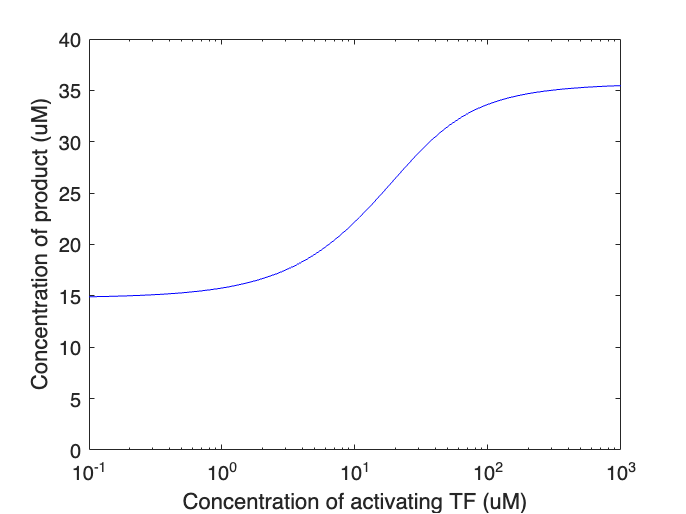

%% 2.3 Parameter sweep across activator concentration

% paramArray = 0:1:100;

paramArray = logspace(-1,3,200); % Uncomment to make a log plot
g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1

    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;

    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

    I = 10; % concentration of inhibitory transcription factor (uM)
    C = paramArray(iParam); % concentration of activatory transcription factor (uM)

    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];


    dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par) - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

    initialCondition = [1,0,0,0,0,0];

    dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
                   dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
                   dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);  % Store the steady-state protein concentration
    
end

% Plot the steady-state protein concentration as a function of the activator concentration
figure; clf;
semilogx(paramArray, g_storage, '-b')  % Use semilogx for a logarithmic x-axis
xlabel('Concentration of activating TF (uM)') 
ylabel('Concentration of product (uM)')
set(gca, 'ylim', [0, 40]);


% Calculate EC50 (half of the maximal response)
max_value = max(g_storage);
EC50_value = paramArray(find(g_storage >= 0.5 * (max_value), 1));  % Find the first value that gives 50% of the maximum

% Display EC50 value
disp(['The EC50 of the activator is: ', num2str(EC50_value), ' uM']);

The EC50 of the activator is: 3.3701 uM


# HW1 PART 2

Assume the concentration of activator is fixed at 10uM. 

Plot the steady-state amount of Protein as a function of the inhibitor concentration.

What is the concentration of inhibitor that results in half its maximal inhibition? This is called the IC50 of the inhibitor. 

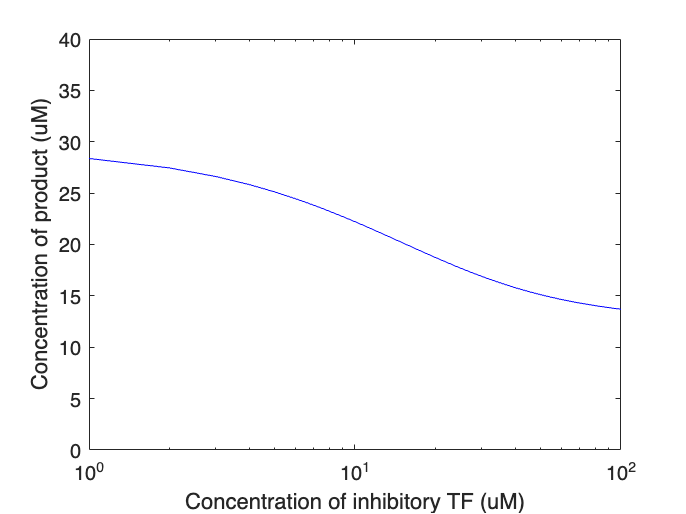


%% 2.3 Parameter sweep across activator concentration

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1

    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;

    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

    I = paramArray(iParam); % concentration of inhibitory transcription factor (uM) % EDIT for HW1
    C = 10; % concentration of activatory transcription factor (uM) % EDIT for HW1

    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];


    dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par) - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

    initialCondition = [1,0,0,0,0,0];

    dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
                   dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
                   dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

% Plot the steady-state protein concentration as a function of the inhibitor concentration
figure; clf;
semilogx(paramArray, g_storage, '-b')  % Use semilogx for a logarithmic x-axis
xlabel('Concentration of inhibitory TF (uM)') 
ylabel('Concentration of product (uM)')
set(gca, 'ylim', [0, 40]);


% Calculate IC50 (half of the maximal inhibition)
min_value = min(g_storage);  % Minimum protein concentration (full inhibition)
max_value = max(g_storage);  % Maximum protein concentration (no inhibition)
IC50_value = paramArray(find(g_storage <= (max_value + min_value) / 2, 1));  % Find first value that gives half-maximal inhibition

% Display IC50 value
disp(['The IC50 of the inhibitor is: ', num2str(IC50_value), ' uM']);

The IC50 of the inhibitor is: 12 uM
